# SIMPLE  K BANDIT

Nombre : Marco Esteban Aguirre Rojas

 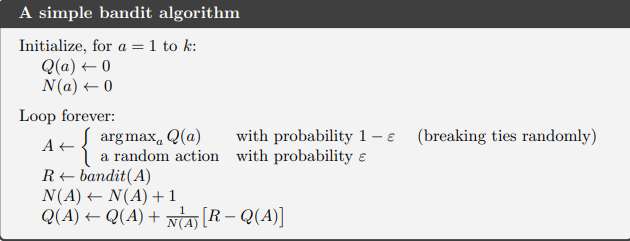

function [Action,Q,R] = simple_bandit(mk_bandis, n_steps, epsilon)
%Imputs :
% mk_bandis = Actual rewards for each bandit (these are the mean rewards)
% n_steps  = number the steps
%epsilon = epsilon
% output Action , Q acumulados , R recompensa acumulada
greedy=zeros(1,n_steps);
if epsilon>0 % creacion del vector probabilidad de ocurrencias 1 - epsilon 
    m           = round(epsilon*n_steps); %Total number 
    greedy(1:m) = ones(1,m);
    m           = randperm(n_steps);
    greedy      = greedy(m);
    clear m
end
Q = zeros(size(mk_bandis));
N = zeros(size(mk_bandis));
for j = 1:n_steps
    if greedy(j) == 0 
        [~, A] = max(Q);
    else
        A = randi([1,10]);
    end
    % R->bandit(A)  a mean q⇤(a) unit variance
    R(j)      = normrnd(mk_bandis(A),1);
    Action(j) = A;
    N(A)      = N(A)+1 ;
    Q(A)      = Q(A) + (1/N(A)) * (R(j) - Q(A)) ;
end